# Seminar 6 - Numerical implementation

**Authors:** Ing. David Vošahlík, prof. Ing. Vladimír Havlena, CSc.

## Introduction

Numerical implementation of the estimation algorithms presented till now will be studied in this seminar. Take a look into the lectures for further details on theory and formulas. We will take the examples that we were solving in the last seminars and try to reimplement them in a smarter and numericaly beneficial way.

## Linear mean square estimate

Linear measurement model will be considered in this section regarding the LMS estimate.

$x=A\;y+b$,

where$A$ and $b$ are the model parameters. Your task will be: 

-  for the given mean and variance generate the samples

- estimate the $A,b$ parameters using linear mean square algorithm with LDL factorization (see lecture slides). 

- Try to play with different inputs of the algorithm (e.g.  number of samples, various means and variances)

*Hint: *look at the Cholesky factorization and then use it to compute the LD factors. (Adopted from [https://en.wikipedia.org/wiki/Cholesky_decomposition](https://en.wikipedia.org/wiki/Cholesky_decomposition) )




n_samples =10;        % number of samples
mu_y = 5;                                       % mean of measured points y
A_real = 7;                                     % true value of the estimated gain parameter
b_real = 9;                                     % true value of the estimated offset parameter
sigma_y = 10;                                   % standard deviation of y
sigma_x = 10;                                   % standard deviation of x


% IMPLEMENT the sample generation

% IMPLEMENT the LDL factorization

A_hat = 0;                                      % IMPLEMENT the estimate
b_hat = 0;                                      % IMPLEMENT the estimate

disp(['Differrence between the real and estimated gain is ' num2str(A_real - A_hat)]);

Differrence between the real and estimated gain is 7


disp(['Differrence between the real and estimated offset term is ' num2str(b_real - b_hat)]);

Differrence between the real and estimated offset term is 9


## Bayesian estimation - numerical implementation

Numericaly beneficial implementation of ARX recursive estimation will be studied in this section. This example is the same as in previous seminar. It is warm started recursive ARX estimation. The only thing that is changed is the numerical implementation with usage of the *ldfill *function. Your task will  be here:

- Go through the script and understand it

- Implement some form of restricted forgetting (exponential or linear) into the ldfill function. 

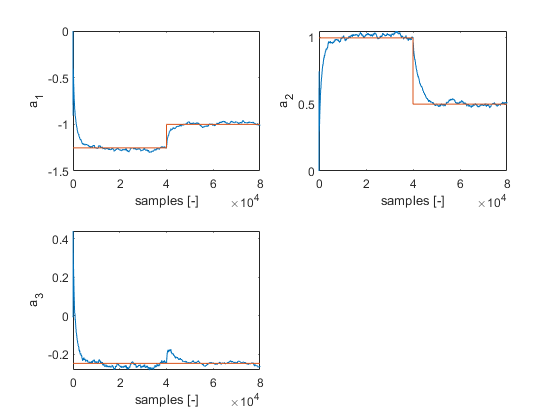

% Generate the data


n_samplesBatch = 30;
[Y, ~, theta_batch, P] = ARXBatch('n_samples', n_samplesBatch);

% Compute the LDL factorization of the joint
% covariance matrix P
C = chol(P + diag(1e-5));
S = diag(diag(C'));
L = C'/S;
D = S^2;

phi = 0.2;

a_old = [1.0000   -1.2526    0.9958   -0.2466];
a_new = [1.0000   -1    0.5   -0.2466];
a = a_old;
b = [0.1432   -0.1737    0.0534];
na = numel(a) - 1;
nb = numel(b);
sig = 10;
f = @(z, a, b) a(2:end)*z(1:na) + b*z(na + 1:end) + sig*randn();
n_samples = [40000; 40000];
y = zeros(sum(n_samples), 1);
y(4:n_samplesBatch) = Y;
u = 150.*randn(sum(n_samples), 1);
theta = zeros(na + nb, sum(n_samples));
theta(:, n_samplesBatch) = theta_batch;
stheta = cell(sum(n_samples), 1);
stheta{n_samplesBatch} = [theta(:, n_samplesBatch), diag(D), L'];
for i = n_samplesBatch + 1:sum(n_samples)
    if i > n_samples(1)
        a = a_new;
    end
    % Regresor construction
    z = [-y(i - 1:-1:i-na); u(i:-1:i-nb + 1)];
    y(i) = f(z, a, b);
    
    
    
    
    data = [z', y(i)];
    
    
    stheta{i} = ldfil(stheta{i-1}, [], data, .9995);
    theta(:,i) = stheta{i}(:,1);
end

% Plots of the estimates and true values
subplot(221);
plot(theta(1,:));
hold on
ind = 2;
plot([0, n_samples(1), n_samples(1), sum(n_samples)], [a_old(ind), a_old(ind), a_new(ind), a_new(ind)])
xlabel('samples [-]');
ylabel('a_1');

subplot(222);
plot(theta(2,:));
hold on
ind = 3;
plot([0, n_samples(1), n_samples(1), sum(n_samples)], [a_old(ind), a_old(ind), a_new(ind), a_new(ind)])
xlabel('samples [-]');
ylabel('a_2');

subplot(223);
plot(theta(3,:));
hold on
ind = 4;
plot([0, n_samples(1), n_samples(1), sum(n_samples)], [a_old(ind), a_old(ind), a_new(ind), a_new(ind)])
xlabel('samples [-]');
ylabel('a_3');

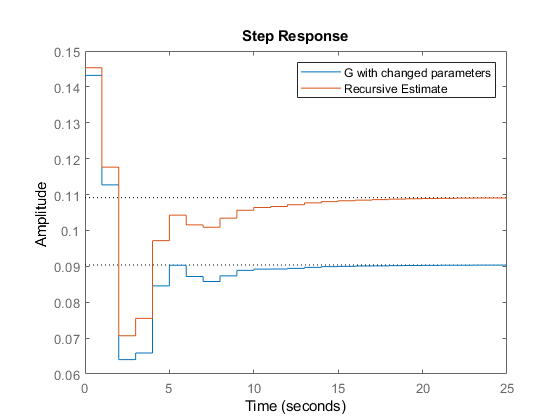


G_recursive = tf(theta(na+1:end, end)',[1 theta(1:na, end)'],1,'Variable','z^-1');
G_recursive.Name = 'Recursive Estimate';
figure;
G_new = tf(b,a_new,1,'Variable','z^-1');
G_new.Name = 'G with changed parameters';
step(G_new);
hold on;
step(G_recursive)
legend show

fix_ylim = ylim;

function [stheta_out, ssigma_out, k, eps, dy] = ldfil(stheta, ssigma, data, phi)
% =========================================================
% LDFIL - ARX identification with LD factorized covariance
% =========================================================
% stheta = [theta,d,L^T]
% ssigma = [nu,nus2]
% data = [z^T,y]
% phi = forgetting coefficient
% =========================================================
% unpack input ============================================
n = length(data) - 1;
z = data(1:n)';
y = data(n+1);
theta = stheta(:,1);
dth = stheta(:,2);
ltht = stheta(:,3:n+2);
% check forgetting factor =================================
if nargin < 4
    phi = 1;
else
    phi = min(phi,1);
    phi = max(phi,.01);
end
% update covariance =======================================
m = [1, zeros(1,n); ltht*z, ltht ];
d = [1; dth ];
% run dydr for i=1 ========================
for j = n+1:-1:2
    mji = m(j,1);
    di = d(1)+mji*mji*d(j);
    mu = mji*d(j)/di;
    d(j) = d(j)*d(1)/di;
    d(1) = di;
    m(j,:) = m(j,:)-mji*m(1,:);
    m(1,:) = m(1,:)+mu*m(j,:);
end
% decompose ===============================
dy = d(1);
dth = d(2:n+1)/phi;
ltht = m(2:n+1,2:n+1);
k = m(1,2:n+1)';
% update theta ============================
eps = y - z'*theta;
theta = theta + k*eps;
stheta_out = [theta,dth,ltht];
% update sigma ============================
if ~isempty(ssigma)
    nu = ssigma(1);
    nus2 = ssigma(2);
    nu = phi*(nu+1);
    nus2 = phi*(nus2+eps*eps/dy);
    ssigma_out = [nu,nus2];
else
    ssigma_out = [];
end
end

function [Y, Z, theta, P] = ARXBatch(varargin)
% You can enforce the estimated model structure with the arguments
% First argument sets the number of parameters in denominator of the TF
% Second argument sets the number of parameters in numerator of the TF


p = inputParser;
addParameter(p,'na',3, @isnumeric);
addParameter(p,'nb',3, @isnumeric);
addParameter(p,'plot',0, @isnumeric);
addParameter(p,'n_samples',100, @isnumeric);
parse(p, varargin{:});
na = p.Results.na;
nb = p.Results.nb;
plot = p.Results.plot;
n_samples = p.Results.n_samples;

[u, y, Ts, G, H] = generate_data(n_samples);





% Output vector
Y=y(1 + max(na,nb):n_samples);

% Regressor
Z=zeros(n_samples - max(na,nb),na+nb);

for i=1 + max(na,nb):size(Z,1) + max(na,nb)
    Z(i - max(na,nb),:)=[-y(i - 1:-1:i-na)', u(i:-1:i-nb + 1)];
end


% Batch identification (least squares)
% theta_batch = pinv(Z)*Y
% badly conditioned formula
theta_batch = (Z'*Z)\Z'*Y;
P_batch = inv(Z'*Z);
% QR algorithm solution
[Q,R] = qr(Z);
theta_batch = R\Q'*Y;
P_batch = inv(R'*R);

theta = theta_batch;
P = P_batch;
if plot
    % Plot result
    G_batch = tf(theta_batch(na+1:end)',[1 theta_batch(1:na)'],Ts,'Variable','z^-1');
    G_batch.Name = 'Batch Estimate';
    figure;
    step(G_batch)
    hold on;
    step(G)
    step(H)
    legend show
    fix_ylim = ylim;
end
end

function [u, y, Ts, G, H] = generate_data(n_samples)
a = [1     7    36   130];
b = [1     5     6];

Ts = 0.2;
H = tf(b, a);
G = c2d(H, Ts);                         % deterministic transfer function
He = tf(1, G.den{1}, Ts);               % noise transfer function

% generate input data and simulate the system
sig = 10;
u = 150.*randn(1,n_samples);
y = lsim(G, u, cumsum(Ts*ones(1, n_samples)) - Ts) + lsim(He, sig.*randn(n_samples, 1), cumsum(Ts*ones(1, n_samples)) - Ts);
end
